smatalb = settings;
smatalb.matlab.appearance.figure.GraphicsTheme.TemporaryValue= 'light'; % Can be set to auto (default), light, or dark

Set model parameters

clear variables;
close all;
clc;
Ts = 0.02; 


% Pendulum 
mdta_pend = {};
mdta_pend.L1 = 0.1;
mdta_pend.m1 = 10;

mdta_pend.g = 9.81;
mdta_pend.q_init = 0;% deg

mdta_pend.cdq1 = 0.5; % damping for both joints, N*m/(rad/s)

% Generate model
mdta_pend.sysLTI = single_pendulum_lin_ss(mdta_pend.m1, mdta_pend.L1, mdta_pend.cdq1, mdta_pend.g);


% Spring damper car 
mdta_cart = {};
mdta_cart.l_length = 0.2; % natural length of spring in meters
mdta_cart.n_cart = 1;
mdta_cart.m = 0.1*ones(mdta_cart.n_cart, 1);
mdta_cart.k = 10 * ones(mdta_cart.n_cart, 1);
mdta_cart.c = 0.5 * ones(mdta_cart.n_cart, 1);
mdta_cart.c_NL = 1.0 * ones(mdta_cart.n_cart, 1);


mdta_cart.scaling = 1.0;
mdta_cart.sys = mdta_cart.scaling*make_ndof_msd_ss(mdta_cart.m, mdta_cart.k, mdta_cart.c);

mdta_cart.sys_dis = c2d(mdta_cart.sys,Ts,'zoh');

Design nonlinear dampers by test probing signals 

% Settings (yours)
N_all = 250;
t_log = (0:Ts:(N_all-1)*Ts)';

freq_band = [0 0.15];
n_period = 1;
n_sample_p_period = floor(N_all/n_period);
amp_range = [-10, 10];

% Number of batches you want
n = 502;
if n < 4
    error('I need at least 2 batches for training, 2 for validation. ')
end

% Pick seeds (fully reproducible)
seed0 = 42;
seed_list = seed0 + (0:n-1);   % e.g. 42,43,...,61

% Preallocate big matrix
U = zeros(N_all, n);

scalll = 1.5;

for k = 1:n
    rng(seed_list(k), 'twister');
    
    u_k = scalll * idinput([n_sample_p_period 1 n_period], 'sine', freq_band, amp_range);
    
    % Ensure it is a column vector and exactly length N_all
    u_k = u_k(:);
    if length(u_k) ~= N_all
        error('Generated signal length is %d, expected %d.', length(u_k), N_all);
    end
    
    U(:, k) = u_k;
end

## Decide SNR ratio

% Hyper para/tuning nobe. 
SNR_target_dB = 10;

G_filt = tf(1,[0 1]) % For filtering in the rho, current is just a static gain


G_filt =
 
  1
 
Static gain.


G_leak = tf(1,[1/50 1]); % Leak integrator for sin/cos. Use later. 


% Simscape init 
t_slx_end = t_log(end);
plant_name = 'M_NLdamper_plant.slx';
plant_name_ = 'M_NLdamper_plant';
u_slx = [t_log(:), U(:,1)];
load_system(plant_name);
set_param(plant_name_, "SimMechanicsOpenEditorOnUpdate", "off");
set_param(plant_name_, "FastRestart", "off");
set_param(plant_name_, "FastRestart", "on");
tmp = sim(plant_name, "SrcWorkspace", "current");


% Data logging init 
N = length(tmp.dq_slx_log.signals.values);
nBatch = n;
y_lti_log_mat = zeros(N, nBatch);
u_log_mat     = zeros(N, nBatch);
y_log_mat     = zeros(N, nBatch); % Noisy with filter 
y_log_mat_unfilt = zeros(N, nBatch); % Noisy without filter  
y_log_mat_clean  = zeros(N, nBatch); % No noise. no filter 
q1_log_mat    = zeros(N, nBatch); %Integration of output 
sin_q1_log_mat = zeros(N, nBatch);
cos_q1_log_mat = zeros(N, nBatch);
tanh_dq1_log_mat = zeros(N, nBatch);% tanh of the output 

% One step Delay function declare 
delay1 = @(x) [0; x(1:end-1)];

% External scheduling signal declare
rho_dim = 7;
rho = zeros(N, rho_dim, nBatch);


% first batch log
y_lti_log_mat(:,1) = tmp.dq_slx_LTI_log.signals.values; % LTI response 
u_log_mat(:,1)     = U(:,1);
y_clean = tmp.dq_slx_log.signals.values(:);
y_noisy = awgn(y_clean, SNR_target_dB, 'measured');
y_log_mat_unfilt(:,1) = y_noisy;
y_log_mat(:, 1) = lsim(G_filt,y_noisy,tmp.dq_slx_log.time,'zoh');
y_log_mat_clean(:,1) = y_clean;


q1_log_mat(:,1)    = tmp.q_slx_log_dis.signals.values;

sin_q1_log_mat(:,1)    = sin(q1_log_mat(:,1) );
cos_q1_log_mat(:,1)    = cos(q1_log_mat(:,1) );
tanh_dq1_log_mat(:,1)    = tanh( y_log_mat(:,1) );




for k = 2:nBatch
    disp("k = " + k);
    u_slx = [t_log(:), U(:,k)];
    simout = sim(plant_name, "SrcWorkspace", "current");

    y_lti_log_mat(:,k) = simout.dq_slx_LTI_log.signals.values;
    u_log_mat(:,k)     = U(:,k);
    y_clean = simout.dq_slx_log.signals.values;    
    y_noisy = awgn(y_clean, SNR_target_dB, 'measured');
    y_log_mat(:, k) = lsim(G_filt,y_noisy,simout.dq_slx_log.time,'zoh');
    y_log_mat_clean(:,k) = y_clean;
    y_log_mat_unfilt(:,k) = y_noisy;


    q1_log_mat(:,k)    = simout.q_slx_log_dis.signals.values;  

    sin_q1_log_mat(:,k)    = sin(q1_log_mat(:,k) );
    cos_q1_log_mat(:,k)    = cos(q1_log_mat(:,k) );
    tanh_dq1_log_mat(:,k)    = tanh( y_log_mat(:,k) );


end

k = 2
k = 3
k = 4
k = 5
k = 6
k = 7
k = 8
k = 9
k = 10
k = 11
k = 12
k = 13
k = 14
k = 15
k = 16
k = 17
k = 18
k = 19
k = 20
k = 21
k = 22
k = 23
k = 24
k = 25
k = 26
k = 27
k = 28
k = 29
k = 30
k = 31
k = 32
k = 33
k = 34
k = 35
k = 36
k = 37
k = 38
k = 39
k = 40
k = 41
k = 42
k = 43
k = 44
k = 45
k = 46
k = 47
k = 48
k = 49
k = 50
k = 51
k = 52
k = 53
k = 54
k = 55
k = 56
k = 57
k = 58
k = 59
k = 60
k = 61
k = 62
k = 63
k = 64
k = 65
k = 66
k = 67
k = 68
k = 69
k = 70
k = 71
k = 72
k = 73
k = 74
k = 75
k = 76
k = 77
k = 78
k = 79
k = 80
k = 81
k = 82
k = 83
k = 84
k = 85
k = 86
k = 87
k = 88
k = 89
k = 90
k = 91
k = 92
k = 93
k = 94
k = 95
k = 96
k = 97
k = 98
k = 99
k = 100
k = 101
k = 102
k = 103
k = 104
k = 105
k = 106
k = 107
k = 108
k = 109
k = 110
k = 111
k = 112
k = 113
k = 114
k = 115
k = 116
k = 117
k = 118
k = 119
k = 120
k = 121
k = 122
k = 123
k = 124
k = 125
k = 126
k = 127
k = 128
k = 129
k = 130
k = 131
k = 132
k = 133
k = 134
k = 135
k = 136
k = 137
k = 138
k = 139
k 

disp(' Decide which one to include in rho:')

 Decide which one to include in rho:


disp(' Decide which one to include in rho:')

 Decide which one to include in rho:


disp(' Decide which one to include in rho:')

 Decide which one to include in rho:


disp(' Decide which one to include in rho:')

 Decide which one to include in rho:


## Decide whether rho has noise 

y_log_mat_rho = y_log_mat_unfilt; % Decide which one to include in rho: rho is noisy without filter 

dq_scale = 1.1 * max(abs(y_log_mat_rho), [], 'all');  % Rho: noise with filter 

% Safety floor in case the data are tiny
dq_scale = max(dq_scale, 1e-8);

disp("dq_scale = " + dq_scale);

dq_scale = 4.7821



% For now, if this script is generating the whole data block before splitting:
u_scale = 1.1 * max(abs(u_log_mat), [], 'all');

% Safety floor in case the data are tiny
u_scale = max(u_scale, 1e-8);

disp("u_scale = " + u_scale);

u_scale = 16.5


z_dq1_log_mat = y_log_mat_rho ./ sqrt(y_log_mat_rho.^2 + dq_scale^2);


u_boud_log_mat = u_log_mat ./ sqrt(u_log_mat.^2 + u_scale^2);

tanh_dq1_log_mat = tanh(y_log_mat_rho);


max(z_dq1_log_mat)

ans =     0.5214    0.5849    0.5170    0.5314    0.5051    0.5399    0.5686    0.5834    0.5365    0.5055    0.6123    0.5034    0.5395    0.5671    0.5336    0.5321    0.5630    0.5635    0.5467    0.4926    0.5485    0.5565    0.6398    0.5754    0.5149    0.5665    0.5391    0.5360    0.5612    0.5247    0.5453    0.5789    0.5369    0.5256    0.5329    0.6101    0.5822    0.5621    0.5280    0.5408    0.5804    0.5241    0.5346    0.5142    0.5547    0.5860    0.5411    0.5075    0.6003    0.5404


max(u_boud_log_mat)

ans =     0.5954    0.6727    0.6727    0.6727    0.6150    0.6727    0.6727    0.6727    0.6727    0.5997    0.6727    0.6217    0.6497    0.6175    0.6590    0.6374    0.6594    0.6727    0.6235    0.5788    0.5765    0.6618    0.6556    0.6185    0.6727    0.6727    0.6727    0.6640    0.6444    0.6169    0.6303    0.6727    0.6229    0.5321    0.6727    0.6727    0.6727    0.6395    0.6727    0.6118    0.6727    0.6291    0.5729    0.6727    0.6420    0.6716    0.6574    0.5666    0.6727    0.6727



for k = 1:nBatch
    rho(:,:,k) = [u_log_mat(:,k), ...
                  delay1(y_log_mat_rho(:,k)), ...
                  delay1(sin_q1_log_mat(:,k)), ...
                  delay1(cos_q1_log_mat(:,k)), ...
                  -delay1(q1_log_mat(:,k)), ...
                  -delay1(q1_log_mat(:,k)), ...
                  delay1(tanh_dq1_log_mat(:,k))];
end




% rho is N x rho_dim x nBatch
size(rho)

ans =    250     7   502



rho = permute(rho, [2 1 3]);   % now rho_dim x N x nBatch

size(rho)

ans =      7   250   502


Check nonlinear effect significant? 

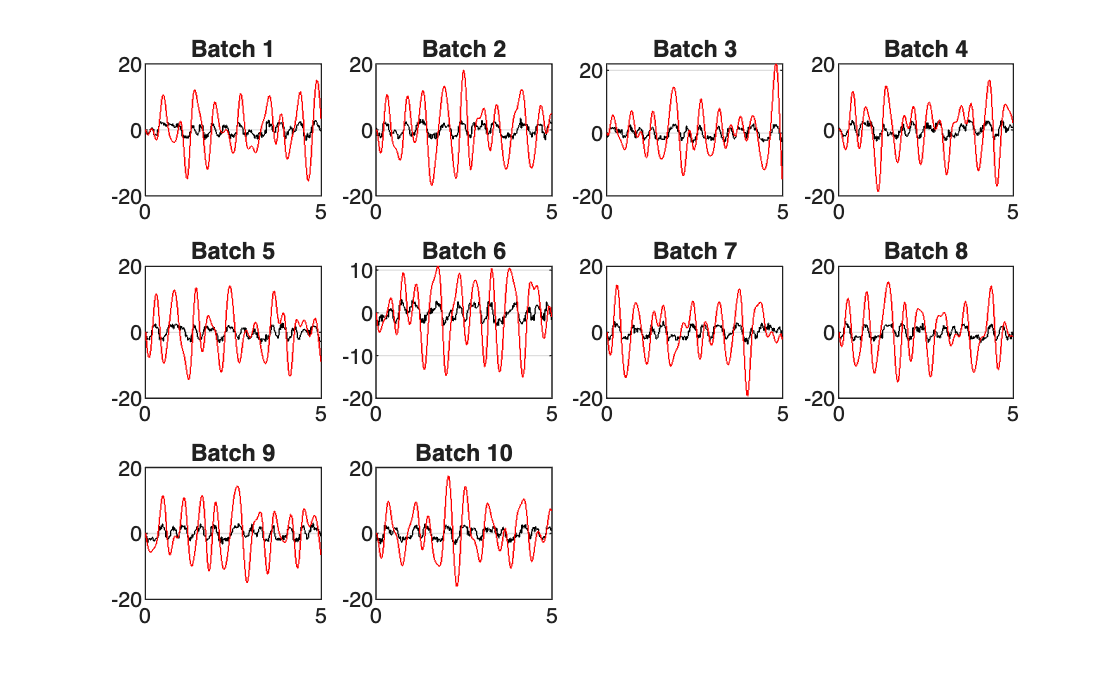

% nBatch = size(y_log_mat, 2);   % or your nBatch variable
nBatch_check = 10;
nCols = ceil(sqrt(nBatch_check));
nRows = ceil(nBatch_check / nCols);

figure;
for k = 1:nBatch_check
    subplot(nRows, nCols, k);
    stairs(t_log, y_log_mat(:,k), '-k'); hold on;
    stairs(t_log, y_lti_log_mat(:,k), '-r'); hold off;
    % xlim([0 10]);
    title(sprintf('Batch %d', k));
    grid on;
end

Check whether a LTI can identify the system 

mean(mse(y_log_mat,y_lti_log_mat))

ans = 37.5565

mean((1-goodnessOfFit(y_lti_log_mat,y_log_mat,'NRMSE'))*100)

ans = -288.0713


u_sysid = u_log_mat(:,1:20);
y_sysid = y_log_mat(:,1:20);
num_exp = size(u_sysid, 2);
data_cell = cell(num_exp, 1);
for k = 1:num_exp
    y_k = y_sysid(:, k);
    u_k = u_sysid(:, k);

    data_cell{k} = iddata(y_k, u_k, Ts);
end

data = merge(data_cell{:});
% Identify state-space model using N4SID
opt = n4sidOptions;
opt.Focus = 'simulation';
n_order = 'best';
sys = n4sid(data,n_order,opt,'DisturbanceModel','none');
mean(sys.Report.Fit.FitPercent)

ans = 57.4070

mean(sys.Report.Fit.MSE)

ans = 0.4533

Check noise level 

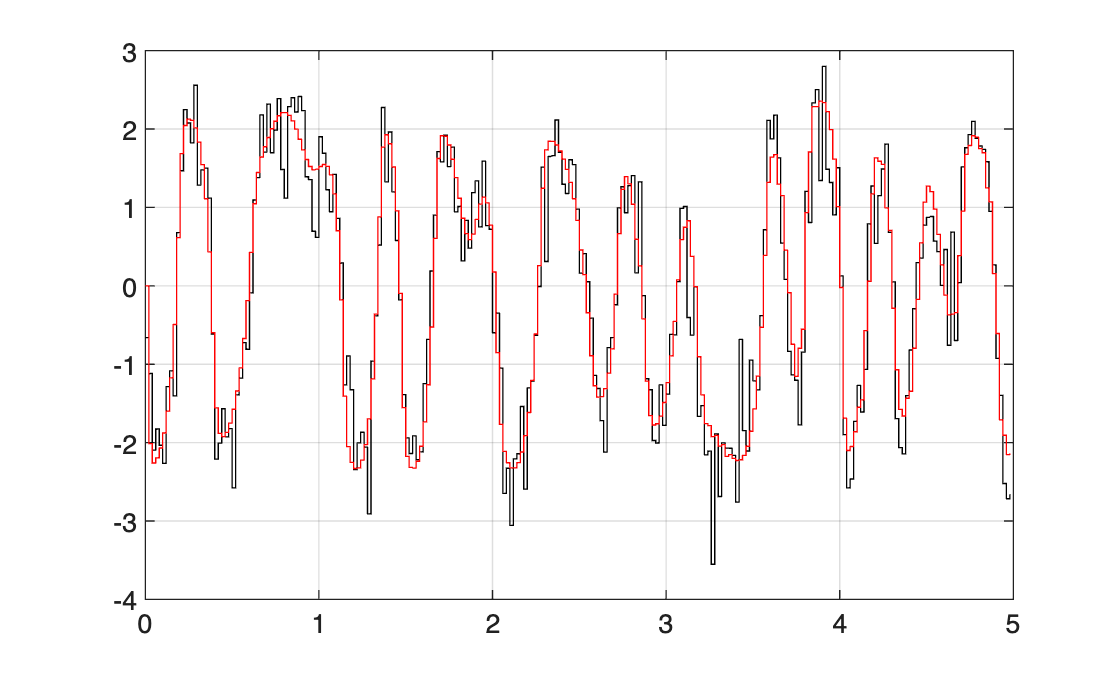

figure;
k_g = 5;
stairs(t_log, y_log_mat_unfilt(:,k_g), '-k'); hold on;
stairs(t_log, y_log_mat_clean(:,k_g), '-r'); hold off;
grid on;

Check scaling for rho 

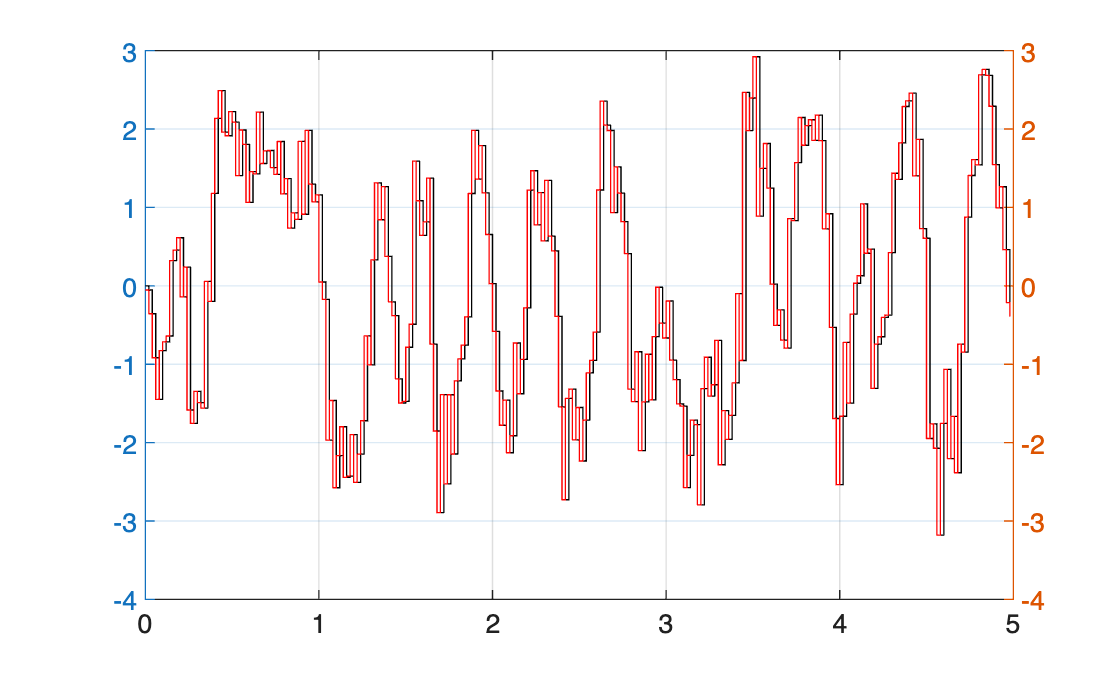

figure;
k_g = 1;
yyaxis left
stairs(t_log, rho(2,:,k_g), '-k'); 
yyaxis right
stairs(t_log, y_log_mat(:,k_g), '-r');
grid on;

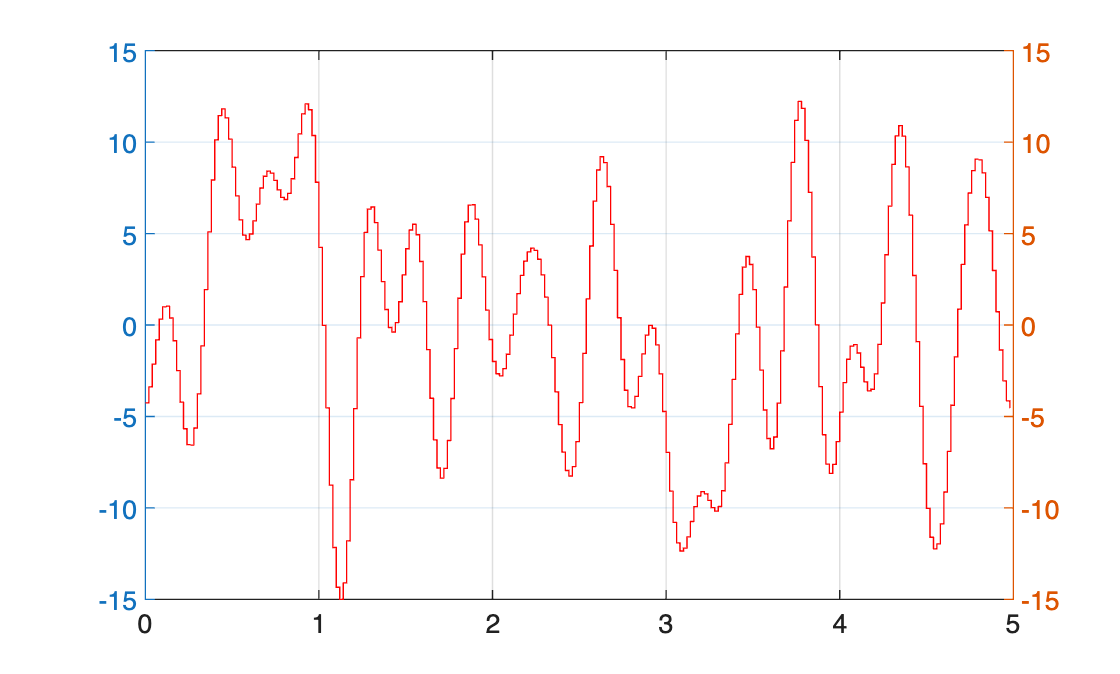


figure;
yyaxis left
stairs(t_log, rho(1,:,k_g), '-k'); 
yyaxis right
stairs(t_log, u_log_mat(:,k_g), '-r');
grid on;

Process data format to save 

ipt_all_mat = U;




disp(' Decide which one to include in y:')

 Decide which one to include in y:


disp(' Decide which one to include in y:')

 Decide which one to include in y:


disp(' Decide which one to include in y:')

 Decide which one to include in y:


disp(' Decide which one to include in y:')

 Decide which one to include in y:


## Decide whether output has noise 

opt_all_mat = y_log_mat_unfilt % This means training output has noise without filter  

opt_all_mat =    -0.0529    0.5775    0.1681    0.2032   -0.6611   -0.0240   -0.5971    0.0296   -0.1116   -0.4180    0.6528    0.8994   -0.1444    0.6177    0.1695   -0.4069   -1.1167   -0.5390    0.5313    0.1613    0.6668    0.4674    0.4330   -0.7280    0.2345   -0.2949   -0.1287   -0.4708   -0.2364    0.2194   -0.2372   -0.7652   -0.5511    0.2630   -0.1193   -0.1047   -0.2649    0.3346    0.1819    0.3578    0.7886    0.2719   -0.3367    0.8061   -0.6743    0.0964    0.0774   -0.2673   -0.3154    0.2774
   -0.3568   -0.2362   -1.2835    0.4341   -1.1183   -1.8074   -1.2103   -1.4148   -0.7882   -0.1882    2.2471   -2.4528   -1.9363    1.0387   -1.1284   -0.7865   -0.8469    1.5187   -0.5330   -0.5515   -0.9603    2.4484    0.0279    0.4043   -0.7562   -0.1128   -0.4036   -1.4498    1.3220    1.2648   -0.4273    0.8581   -0.0381    0.7527    2.4453   -0.3159    1.1988   -0.8078    0.5991   -2.2752    1.9900   -0.2482   -0.2790   -0.2009    0.9077    1.2747    1.1839   -1.1469   -1

opt_all_mat_clean = y_log_mat_clean;



%% Basic checks
[N_u, nBatch_u] = size(ipt_all_mat);
[N_y, nBatch_y] = size(opt_all_mat);

if N_u ~= N_y
    error('U and y_log_mat must have the same number of rows. Got %d vs %d.', N_u, N_y);
end
if nBatch_u ~= nBatch_y
    error('U and y_log_mat must have the same number of columns (batches). Got %d vs %d.', nBatch_u, nBatch_y);
end

N = N_u;
nBatch = nBatch_u;

%% Split: 17 training batches, 3 validation batches
nTrainBatches = 500;
nValidBatches = nBatch - nTrainBatches;

% Choose split mode: 'fixed' or 'random'
split_mode = 'fixed';   % <-- change to 'fixed' if you want 1:17 train, 18:20 valid

if strcmpi(split_mode, 'fixed')
    idx_train = 1:nTrainBatches;
    idx_valid = (nTrainBatches+1):nBatch;
elseif strcmpi(split_mode, 'random')
    rng(42);                     % reproducible split
    perm = randperm(nBatch);
    idx_train = perm(1:nTrainBatches);
    idx_valid = perm(nTrainBatches+1:end);
else
    error('Unknown split_mode. Use ''fixed'' or ''random''.');
end

% Create train/valid matrices
ipt_train_mat = ipt_all_mat(:, idx_train);      % N x 17
ipt_valid_mat = ipt_all_mat(:, idx_valid);      % N x 3

opt_train_mat = opt_all_mat(:, idx_train);      % N x 17
opt_valid_mat = opt_all_mat(:, idx_valid);      % N x 3


opt_train_mat_clean = opt_all_mat_clean(:, idx_train);      % N x 17
opt_valid_mat_clean = opt_all_mat_clean(:, idx_valid);      % N x 3


opt_train_delay_mat = [zeros(1, size(opt_train_mat,2));
                       opt_train_mat(1:end-1, :)];
opt_valid_delay_mat = [zeros(1, size(opt_valid_mat,2));
                       opt_valid_mat(1:end-1, :)];

%% Quick sanity checks
disp('Train batches idx:'); disp(idx_train);

Train batches idx:
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100   101   102   103   104   105   106   107   108   109   110   111   112   113   114   115   116   117   118   119   120   121   122   123   124   125   126   127   128   129   130   131   132   133   134   135   136   137   138   139   140   141   142   143   144   145   146   147   148   149   150   151   152   153   154   155   156   157   158   159   160   161   162   163   

disp('Valid batches idx:'); disp(idx_valid);

Valid batches idx:
   501   502



disp('Last 3 rows: opt_train_mat vs opt_train_delay_mat (should be shifted by 1)');

Last 3 rows: opt_train_mat vs opt_train_delay_mat (should be shifted by 1)


disp(opt_train_mat(end-2:end, :));

    0.4621    2.5008   -1.3247    0.7366   -2.5216   -0.3629    0.5767   -0.9690    0.5783    1.8424    1.1555   -1.1243   -0.5775   -0.6808    2.8324   -1.5647   -2.4588   -2.8803    3.1226    1.1308   -0.7662   -1.0186    2.6344    1.8061    0.1350    0.1548   -0.5207   -2.0502   -0.7225   -2.3986    0.1128   -1.5795   -1.4135    2.4608   -1.8926    1.6472    0.7307   -1.5368   -0.2190   -0.2411    1.6814   -1.1205    1.9069   -2.1947    0.0581    0.5608    2.1483    1.6498    0.1298    1.9018   -0.4472   -2.0849   -0.4085   -0.6775    2.5782    2.2334    0.3340   -1.9905    1.9364   -1.3422    1.2614    2.0499    1.1275    2.2663    2.5277    1.0299    1.9554    1.7637   -2.5359    1.7373   -1.8946    2.8278   -1.0702   -1.0406   -1.4434   -0.6157    1.3945   -1.2126   -0.4902    1.9753   -1.3590    2.3062   -1.4869    1.6576   -2.1347   -1.1633   -1.7463    1.5227   -0.3443    1.8836    1.7652   -2.1199    1.1902   -0.9574   -1.1955   -2.0095    1.9826   -0.9257    1.4226    0.1383

disp(opt_train_delay_mat(end-2:end, :));

    1.2638    2.7304   -2.2119    1.1361   -1.3968    0.8746    0.8758   -1.9855   -0.0059    1.8980    0.9078   -1.4743    0.1195   -1.6177    1.8547   -1.8329   -1.4054   -0.9046    1.6354   -0.1080   -0.8208   -0.9653    1.8176    1.7008    0.9328    1.1429    0.0456   -2.3289   -1.4159   -2.4883    0.0875   -1.9597   -1.2566    1.8510   -1.3574    2.3603   -0.5021   -2.7408    0.1857    0.6741    1.8118   -2.4566    2.2411   -2.1392   -0.1862   -1.4921    2.7112    2.6842   -1.3281    1.4173    0.0473   -2.1665    1.1076   -0.7558    2.3179    2.5671    1.0266   -1.9529    2.3540   -0.9704    1.2461    2.3608    3.0472    2.2323    0.5813    1.5927    1.7523    1.9556   -2.2560    1.1460   -2.1876    1.8937   -1.3649   -0.9138   -0.9739   -0.4906    1.3306    0.0003   -0.6347    1.3942   -0.7368    0.9455   -1.8656    2.4951   -1.3819   -1.6770   -1.6172    2.5083   -0.8979    1.4139    2.0055   -1.7213    1.0294    0.3827   -1.1550   -2.3095    2.5604   -1.1027    0.7936    0.8500


%% Assume rho is rho_dim x N x nBatch
[rho_dim_chk, N_rho, nBatch_rho] = size(rho);

if N_rho ~= N || nBatch_rho ~= nBatch
    error('rho size mismatch. Expected rho_dim x %d x %d, got %d x %d x %d.', ...
          N, nBatch, rho_dim_chk, N_rho, nBatch_rho);
end

% Split rho using same batch indices
rho_train = rho(:, :, idx_train);   % rho_dim x N x nTrainBatches
rho_valid = rho(:, :, idx_valid);   % rho_dim x N x nValidBatches


dta.ipt_train_mat = reshape(ipt_train_mat, [1 size(ipt_train_mat)]);
dta.ipt_valid_mat = reshape(ipt_valid_mat, [1 size(ipt_valid_mat)]);

dta.opt_train_mat = reshape(opt_train_mat, [1 size(opt_train_mat)]);
dta.opt_train_mat_clean = reshape(opt_train_mat_clean, [1 size(opt_train_mat_clean)]);
dta.opt_train_delay_mat = reshape(opt_train_delay_mat, [1 size(opt_train_delay_mat)]);

dta.p_train_delay_mat = rho_train;
dta.p_valid_delay_mat = rho_valid;


dta.opt_valid_mat = reshape(opt_valid_mat, [1 size(opt_valid_mat)]);

dta.int_ipt_train_mat = zeros(size(dta.ipt_train_mat));
dta.int_ipt_valid_mat = zeros(size(dta.ipt_valid_mat));

dta.N_train = N;
dta.N_valid = N;
dta.n_train = nTrainBatches;
dta.n_valid = nValidBatches;
dta.t = t_log;
dta.G_leak = G_leak;
dta.G_filt = G_filt;
dta.Ts = Ts;
dta.sysLTI = mdta_cart.sys

dta = struct with fields:
          ipt_train_mat: [1×250×500 double]
          ipt_valid_mat: [1×250×2 double]
          opt_train_mat: [1×250×500 double]
    opt_train_mat_clean: [1×250×500 double]
    opt_train_delay_mat: [1×250×500 double]
      p_train_delay_mat: [7×250×500 double]
      p_valid_delay_mat: [7×250×2 double]
          opt_valid_mat: [1×250×2 double]
      int_ipt_train_mat: [1×250×500 double]
      int_ipt_valid_mat: [1×250×2 double]
                N_train: 250
                N_valid: 250
                n_train: 500
                n_valid: 2
                      t: [250×1 double]
                 G_leak: [1×1 tf]
                 G_filt: [1×1 tf]
                     Ts: 0.0200
                 sysLTI: [1×1 ss]


dta.dq_scale = dq_scale

dta = struct with fields:
          ipt_train_mat: [1×250×500 double]
          ipt_valid_mat: [1×250×2 double]
          opt_train_mat: [1×250×500 double]
    opt_train_mat_clean: [1×250×500 double]
    opt_train_delay_mat: [1×250×500 double]
      p_train_delay_mat: [7×250×500 double]
      p_valid_delay_mat: [7×250×2 double]
          opt_valid_mat: [1×250×2 double]
      int_ipt_train_mat: [1×250×500 double]
      int_ipt_valid_mat: [1×250×2 double]
                N_train: 250
                N_valid: 250
                n_train: 500
                n_valid: 2
                      t: [250×1 double]
                 G_leak: [1×1 tf]
                 G_filt: [1×1 tf]
                     Ts: 0.0200
                 sysLTI: [1×1 ss]
               dq_scale: 4.7821


dta.u_scale = u_scale;

#### Check the passivity of the training data

% Plot passivity (prefix inner-product) for BOTH training and validation
% Assumes you already have:
%   ipt_train_mat : N x nTrain
%   opt_train_mat : N x nTrain
%   ipt_valid_mat : N x nValid
%   opt_valid_mat : N x nValid

%% Checks
N = size(ipt_train_mat, 1);
if size(opt_train_mat,1) ~= N || size(ipt_valid_mat,1) ~= N || size(opt_valid_mat,1) ~= N
    error('All ipt/opt matrices must have the same number of rows (N).');
end

nTrain = size(ipt_train_mat, 2);
nValid = size(ipt_valid_mat, 2);

%% Compute cumulative supply S(t,k) = sum_{tau<=t} u(tau,k)*y(tau,k)
S_train = cumsum(ipt_train_mat .* opt_train_mat, 1);   % N x nTrain
S_valid = cumsum(ipt_valid_mat .* opt_valid_mat, 1);   % N x nValid

%% Report minima
min_train_per_batch = min(S_train, [], 1);
min_valid_per_batch = min(S_valid, [], 1);

[min_train_all, idx_train_lin] = min(S_train, [], 'all');
[t_train_min, k_train_min] = ind2sub(size(S_train), idx_train_lin);

[min_valid_all, idx_valid_lin] = min(S_valid, [], 'all');
[t_valid_min, k_valid_min] = ind2sub(size(S_valid), idx_valid_lin);

fprintf('TRAIN: worst prefix energy = %.6g at t=%d, batch=%d\n', min_train_all, t_train_min, k_train_min);

TRAIN: worst prefix energy = -12.8326 at t=1, batch=12


fprintf('VALID: worst prefix energy = %.6g at t=%d, batch=%d\n', min_valid_all, t_valid_min, k_valid_min);

VALID: worst prefix energy = 0.673599 at t=2, batch=2



viol_train = find(min_train_per_batch < 0);
viol_valid = find(min_valid_per_batch < 0);

if isempty(viol_train)
    fprintf('TRAIN: no violations (all min >= 0)\n');
else
    fprintf('TRAIN: violations in batches: ');
    fprintf('%d ', viol_train);
    fprintf('\n');
end

TRAIN: violations in batches: 

2 3 4 8 12 15 18 19 20 21 23 24 25 29 32 33 35 36 37 38 40 42 43 45 50 51 54 55 56 58 59 60 62 65 68 69 70 72 77 78 79 80 81 84 85 86 88 89 91 92 93 94 99 101 102 104 105 106 107 109 111 112 114 115 117 120 123 124 125 127 129 130 134 135 136 137 138 140 141 142 143 144 146 147 150 151 152 153 154 155 157 158 159 160 161 162 163 164 165 166 167 168 170 171 172 173 174 179 180 185 186 187 188 189 193 195 197 198 199 200 201 204 205 206 208 209 210 211 212 215 216 219 221 222 223 224 225 226 227 228 231 232 234 236 237 238 240 242 244 245 247 251 253 254 257 258 259 260 261 262 263 264 266 267 268 269 270 272 273 276 278 279 282 284 286 287 290 292 293 294 298 301 305 307 310 313 314 315 317 320 321 323 324 325 326 327 328 332 334 338 340 341 343 345 346 350 353 355 359 360 361 366 367 369 370 375 376 378 382 383 384 385 386 387 388 389 390 391 392 393 394 397 399 400 401 402 403 404 405 406 407 408 411 412 419 421 423 424 425 426 427 429 430 431 433 435 436 437 438 440 441 445 446 447 4


if isempty(viol_valid)
    fprintf('VALID: no violations (all min >= 0)\n');
else
    fprintf('VALID: violations in batches: ');
    fprintf('%d ', viol_valid);
    fprintf('\n');
end

VALID: no violations (all min >= 0)


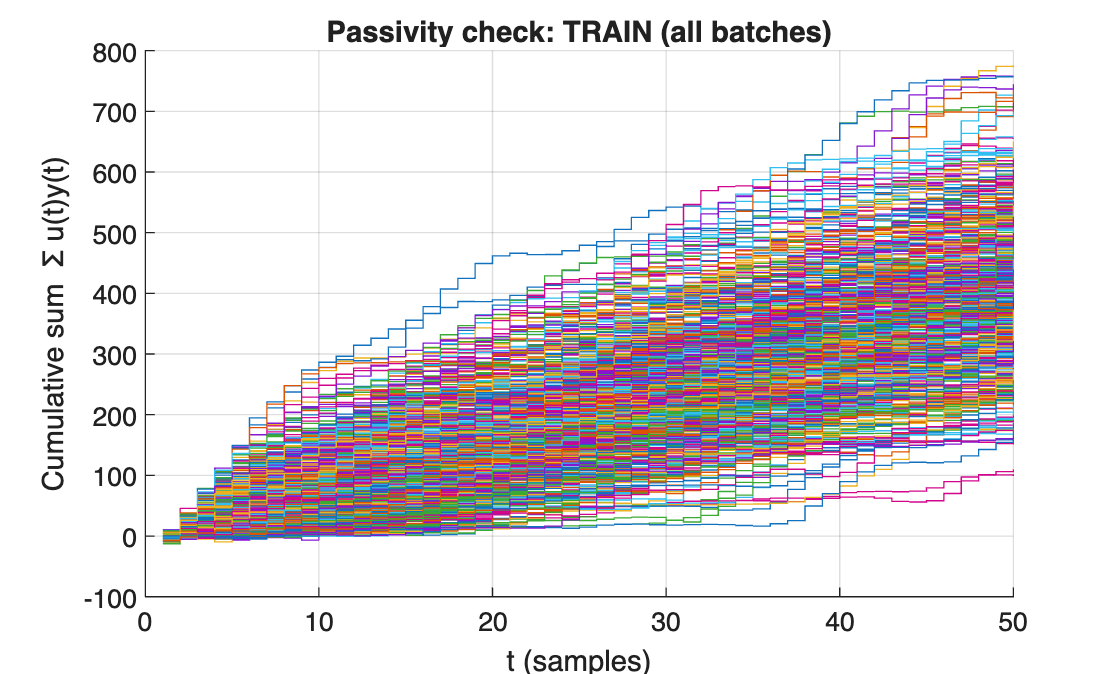


%% Plot settings
Tplot = min(50, N);
N_t = (1:Tplot).';

%% Plot 1: Training
figure; hold on; grid on;
for k = 1:nTrain
    stairs(N_t, S_train(1:Tplot, k));
end
xlim([0, Tplot]);
xlabel('t (samples)');
ylabel('Cumulative sum  \Sigma u(t)y(t)');
title('Passivity check: TRAIN (all batches)');
hold off;

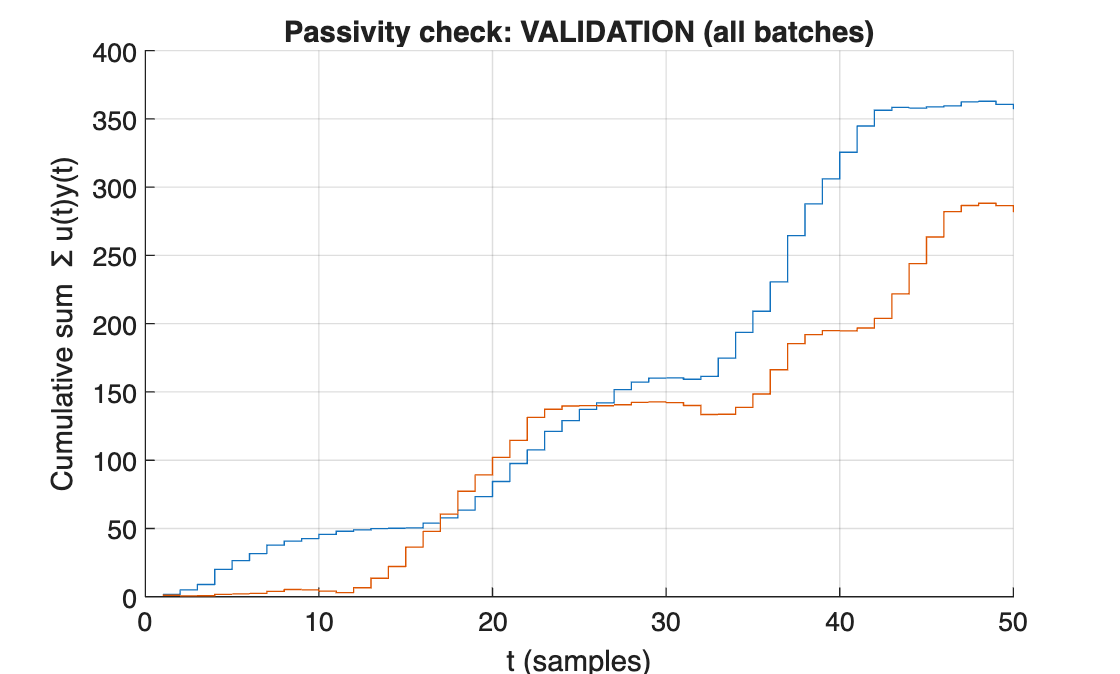


%% Plot 2: Validation
figure; hold on; grid on;
for k = 1:nValid
    stairs(N_t, S_valid(1:Tplot, k));
end
xlim([0, Tplot]);
xlabel('t (samples)');
ylabel('Cumulative sum  \Sigma u(t)y(t)');
title('Passivity check: VALIDATION (all batches)');
hold off;

save('Data_M_NLdamper_500B_OneCart_SNR10','dta');

Local functions

function sys = make_ndof_msd_ss(m, k, c)
%MAKE_NDOF_MSD_SS Continuous-time state-space model of an n-DOF cascaded mass-spring-damper system.
%
%   sys = make_ndof_msd_ss(m, k, c)
%
%   System:
%       n masses are cascaded in one dimension.
%       Mass 1 is connected to the wall by spring k(1) and damper c(1).
%       Mass i-1 and mass i are connected by spring k(i) and damper c(i),
%       for i = 2,...,n.
%
%   Input:
%       u = external force applied to the last mass, mass n.
%
%   Output:
%       y = velocity of the last mass, v_n.
%
%   State vector:
%       x = [p1; v1; p2; v2; ...; pn; vn]
%
%   where:
%       p_i = displacement of mass i
%       v_i = velocity of mass i
%
%   Continuous-time state-space model:
%       dx/dt = A x + B u
%       y     = C x + D u
%
%   Required dimensions:
%       m must be length n.
%       k must be length n.
%       c must be length n.
%
%   Meaning of parameters:
%       m(i) = mass of cart i
%       k(1) = spring constant between wall and mass 1
%       c(1) = damping coefficient between wall and mass 1
%       k(i) = spring constant between mass i-1 and mass i, for i >= 2
%       c(i) = damping coefficient between mass i-1 and mass i, for i >= 2

    arguments
        m (:,1) double {mustBePositive}
        k (:,1) double {mustBeNonnegative}
        c (:,1) double {mustBeNonnegative}
    end

    n = length(m);

    if length(k) ~= n
        error('Length of k must be equal to length of m. k(1) is wall-to-mass-1; k(i) is between masses i-1 and i.');
    end

    if length(c) ~= n
        error('Length of c must be equal to length of m. c(1) is wall-to-mass-1; c(i) is between masses i-1 and i.');
    end

    A = zeros(2*n, 2*n);
    B = zeros(2*n, 1);
    C = zeros(1, 2*n);
    D = 0;

    % Kinematic equations:
    %   dot p_i = v_i
    for i = 1:n
        pos_idx = 2*i - 1;
        vel_idx = 2*i;

        A(pos_idx, vel_idx) = 1;
    end

    % Dynamic equations:
    %   m_i dot v_i = spring forces + damping forces + external force if i = n
    for i = 1:n
        pos_i = 2*i - 1;
        vel_i = 2*i;

        acc_row = vel_i;

        % Contribution from the left connection.
        % For i = 1, this is the wall-to-mass-1 connection:
        %       force = -k(1) p_1 - c(1) v_1
        %
        % For i >= 2, this is the connection between mass i-1 and mass i:
        %       force = -k(i)(p_i - p_{i-1}) - c(i)(v_i - v_{i-1})
        if i == 1
            A(acc_row, pos_i) = A(acc_row, pos_i) - k(1)/m(i);
            A(acc_row, vel_i) = A(acc_row, vel_i) - c(1)/m(i);
        else
            pos_left = 2*(i-1) - 1;
            vel_left = 2*(i-1);

            A(acc_row, pos_i) = A(acc_row, pos_i) - k(i)/m(i);
            A(acc_row, vel_i) = A(acc_row, vel_i) - c(i)/m(i);

            A(acc_row, pos_left) = A(acc_row, pos_left) + k(i)/m(i);
            A(acc_row, vel_left) = A(acc_row, vel_left) + c(i)/m(i);
        end

        % Contribution from the right connection.
        % For i < n, this is the connection between mass i and mass i+1:
        %       force = k(i+1)(p_{i+1} - p_i) + c(i+1)(v_{i+1} - v_i)
        if i < n
            pos_right = 2*(i+1) - 1;
            vel_right = 2*(i+1);

            A(acc_row, pos_i) = A(acc_row, pos_i) - k(i+1)/m(i);
            A(acc_row, vel_i) = A(acc_row, vel_i) - c(i+1)/m(i);

            A(acc_row, pos_right) = A(acc_row, pos_right) + k(i+1)/m(i);
            A(acc_row, vel_right) = A(acc_row, vel_right) + c(i+1)/m(i);
        end
    end

    % Input force applied to the last mass:
    %       dot v_n receives u / m_n
    B(2*n, 1) = 1/m(n);

    % Output velocity of the last mass:
    %       y = v_n
    C(1, 2*n) = 1;

    sys = ss(A, B, C, D);

    sys.InputName = {'force_on_last_mass'};
    sys.OutputName = {'velocity_last_mass'};

    state_names = cell(2*n, 1);

    for i = 1:n
        state_names{2*i - 1} = sprintf('p%d', i);
        state_names{2*i} = sprintf('v%d', i);
    end

    sys.StateName = state_names;
end

function sys = single_pendulum_lin_ss(m, L, cdq, g)
%SINGLE_PENDULUM_LIN_SS Linearised LTI model (down equilibrium) for a
%single pendulum with a point mass at the end and joint viscous damping.
%
% ODE (nonlinear, zero at downward):
%   m*L^2 * ddtheta + cdq * dtheta + m*g*L * sin(theta) = tau
%
% Linearised about theta = 0:
%   m*L^2 * ddtheta + cdq * dtheta + m*g*L * theta = tau
%
% States: x = [theta; dtheta]
% Input : u = tau (joint torque)
% Output: y = dtheta (angular velocity)
%
% Parameters:
%   m    : point mass (kg)
%   L    : length from pivot to mass (m)
%   cdq  : viscous damping at joint (N*m*s/rad)
%   g    : gravitational acceleration (m/s^2). Optional; default 9.81.
%
% Output:
%   sys : continuous-time state-space (ss) model

    if nargin < 4
        g = 9.81;
    end

    % Basic checks
    if m <= 0
        error('m must be positive.');
    end
    if L <= 0
        error('L must be positive.');
    end
    if cdq < 0
        error('cdq must be non-negative.');
    end
    if g <= 0
        error('g must be positive.');
    end

    % Linearised dynamics: J*ddtheta + cdq*dtheta + k*theta = tau
    J = m * L^2;      % inertia about pivot for point mass
    k = m * g * L;    % linearised gravity stiffness about downward

    A = [ 0,         1;
         -k/J,   -cdq/J ];

    B = [ 0;
          1/J ];

    % Output y = dtheta
    C = [0 1];
    D = 0;

    sys = ss(A, B, C, D);
end

